# V768 - Measuring Vision with Psychophysics

## Lab 2 - Signal Detection Theory

**How well can a person distinguish between information and noise?** In this lab, you will learn about signal detection theory (SDT), which gives us a framework that we can use to answer that question.

As a primer, recall the method of constant stimuli experiment from last week's lab. In most trials, a grating (signal) was present, but in some, the grating was set to have the same luminance as the background. Likewise, you probably reported seeing (detecting) a grating in most trials but reported not seeing a grating in some. We could use that information to divide those trials into four groups:

By the end of this tutorial you will understand how dividing your trials into hits, misses, false alarms, and correct rejections will allow you to measure the detectabilty of a particular stimulus for an observer.

*Based on *[*https://gru.stanford.edu/doku.php/tutorials/sdt*](https://gru.stanford.edu/doku.php/tutorials/sdt)* by Justin Gardner, Stanford University.*

### Learning Outcomes

(i.e., what you will be able to do at the end of this lab)

- Define and calculate hits, misses, false alarms, and correct rejections.

- Explain the role of the criterion in determining the # of hits, misses, false alarms and correct rejections.

- Calculate dprime.  Describe how this measure of sensitivity can be independent of the decision criterion of the observer.

### Questions

- What are the two ways to be right in an signal detection experiment?

- Write a figure caption for the 3 panel figure in the section on *simulating and evaluating the response of the ideal observer*.

- Report the hits, misses, false alarms, and correct rejections in table form for criterion values of 0.5, 1.5 and -0.1. (Hint: Change the criterion value in the section below and run it again.)

- Describe in words how changing the criterion affects the performance of the ideal observer. 

## Signal Detection Theory

We are going to simulate a signal detection experiment and an "ideal observer" (an observer who behaves exactly according to signal detection theory). This is a useful thing to do when trying to understand any decision model, experimental method, or an analysis tool. You get to control and play around with the simulation to see what effect it has on the analysis that comes out.

Signal detection is a general framework in which an observer tries to detect the presence or absence of a signal. What's an example of a signal detection task? Anything, really. One example is whether you can see if a candle is lit in a window 1 mile away. It could be to detect whether you see a friend's face within a crowd. Sometimes these experiments are called “Yes / No” experiments in that the observer has to say either “Yes” I saw it or “No” I did not. Sometimes there is a signal there (the candle was lit, your friend was in the crowd) and these are called signal-present trials. Sometimes there is no signal there (the candle wasn't lit, your friend wasn't in the crowd) and those are called signal-absent trials.

You did a Yes/No experiment last week in the method of constant stimuli portion of the lab. Sometimes there was a grating in the circle, sometimes there wasn't.

## 1. Visualizing Hits/Misses/False Alarms/Correct Rejections

Subjects are right if they correctly detect a signal when it is present (hit) or when the correctly say the signal absent (correct reject). Similarly, subjects can make two kinds of mistakes - they can say that the signal was there when it was actually absent (false-alarm) or they can say that the signal was not there when it actually was (miss). These kinds of errors have completely unhelpful names in statistics (type 1 or alpha for false-alarm and type 2 or beta for miss), so its more helpful to think about them in terms of misses and false-alarms.

We often visualize these components that form the core of signal detection theory like this: 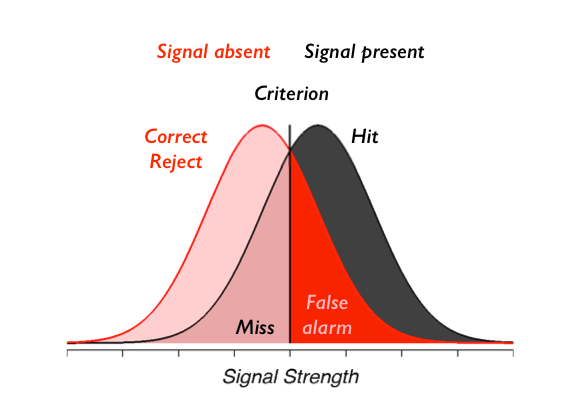

**Why do we represent the signal absent and signal present trials as distributions?**  The x-axis here actually represents "internal signal strength".  You could think of each distribution as a 1D representation of the neural signal for that stimulus in the brain.  Even if I present the same stimulus 100 times, the neural response will not be identical because of neural noise.  Thus we represent the signal-absent and signal-present stimulus conditions as distributions.  If those distributions are overlapping, then we will make mistakes (misses and false alarms) regardless of where we set the decision criterion.

**What is a decision criterion?** In this 1D signal detection theory example, the decision criterion is the signal strength threshold for the ideal observer.  The ideal observer will say that the signal was present if the signal strength on this trial was above the criterion.  And similarly, the ideal observer will say that the signal was absent if the signal strength on this trial was below the criterion.

A key idea that motivates the theory of signal detection is that you want to measure sensitivity (how good are subjects at detecting that faint candle light), while accounting for this cognitive factor - what criteria the subject uses. A subject can have a very conservative criteria (only say there is a light if they are very sure). This will lower false-alarm rates, but then the subject may make more misses. A subject alternatively can change their criteria so that they are less prone to missing, but then they will make more false-alarms. Signal detection theory allows you to compute sensitivity and criteria separately from subject responses (i.e. the hit and false-alarm rates) so that you can determine how sensitive a subject is regardless of what arbitrary criteria they used. 

## 2. Simulating signal-present and signal-absent trials.

On each trial, our ideal observer receives a signal sampled from either the signal present distribution or the signal absent distribution. The observer chooses to say “signal present” when the signal they see on that trial is above criterion and “signal absent” otherwise.

Signal-present (or signal) trials should come from some gaussian distribution and signal-absent (or noise) trials should come from another gaussian distribution.  These two distributions differ only in their means. This is an assumption about the process that is called **iid** - the signal and noise come from **i**ndependent **i**dentical **d**istributions. 


% First we need to determine which trials will be signal and which will be
% signal-absent (or noise)
ntrials = 1000; % there will be n trials
% we choose to make the trials so that they are 1/2 signal present and 1/2 signal absent
signalPresentAbsent =  [ones(ntrials/2,1);zeros(ntrials/2,1)]; 
signalPresentAbsent = Shuffle(signalPresentAbsent); % shuffle the trial order

% Then we need to simulate the signal for the ideal observer on every trial.
for i = 1:length(signalPresentAbsent) % cycle over every trial
  % if signal present trial
  if signalPresentAbsent(i) == 1
    % then pull a random draw from the signal distribution with mean = 1 and std = 1
    signal(i) = random('norm',1,1);
  else
    % otherwise it is a noise trial so pull a random draw from the noise distribution with mean = 0 and std = 1
    signal(i) = random('norm',0,1);
  end
end


#### Visualize the signal-present and signal-absent trials we just generated as 2 histograms.

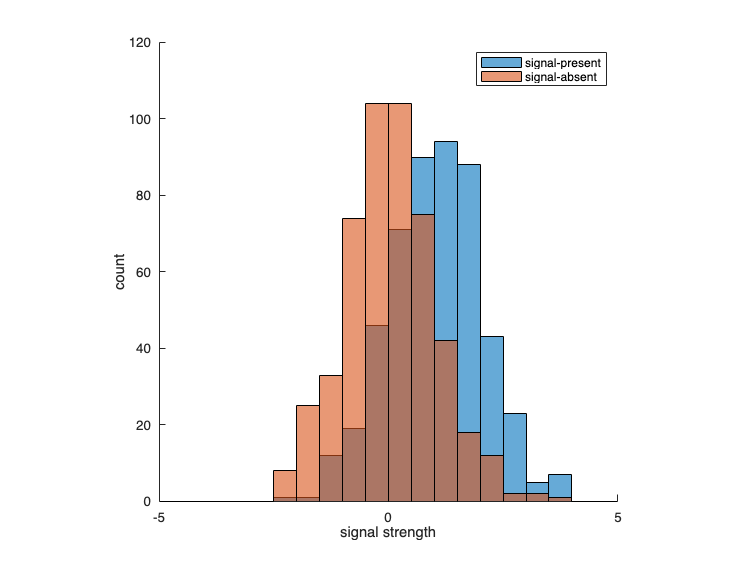

figure(); clf;
% Plot the signal-present distribution and the signal-absent distribution
 hold on;
% set up the x axis to have the same histogram bins for both trial types
histogram_bins = -5:.5:5;
% show signal present distribution
histogram(signal(signalPresentAbsent==1),histogram_bins);
% show signal absent distribution
histogram(signal(signalPresentAbsent==0),histogram_bins);
xlabel('signal strength');
ylabel('count');
box off;
axis square;
legend('signal-present','signal-absent')

## Check the distributions.

(always good to double check everything when programming to make sure that things are working out the way you expected). You can confirm numerically that the means and standard deviations of the signal-present and signal-absent distributions are what they should be:

% display mean of signal present distribution (should be near 1)
mean(signal(signalPresentAbsent==1))

ans = 0.9979

% display std of signal present distribution (should be near 1)
std(signal(signalPresentAbsent==1))

ans = 0.9824

% mean and standard deviation for signal absent distribution should be 0 and 1 respectively
mean(signal(signalPresentAbsent==0))

ans = 0.0618

std(signal(signalPresentAbsent==0))

ans = 0.9959

## Simulating and evaluating the response of the ideal observer

Now we are going to simulate an ideal observer. The ideal observer will choose signal present (response=1) when the signal they get to see (signal array from above) is greater than their decision criterion and they will choose signal absent (response=0) when the signal is below their decision criterion.

Let's start by making the criterion right in between the signal-present and signal-absent distributions that we created above. That is, let's set criterion=0.5 and make an array of responses.

colors = [0 0.4470 0.7410; 
    0.8500 0.3250 0.0980];

% setting up the "internal criterion"
criterion = .5;

% calculating the ideal observer response
response = signal >= criterion;


#### **Visualize the ideal observer responses.**

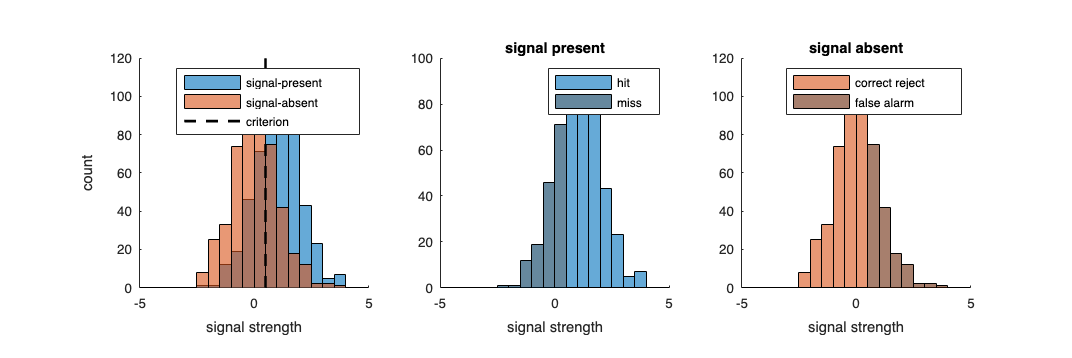

% let's add the criterion to the visualization of the two distributions
figure(); clf;
subplot(131); hold on;
% set up the x axis to have the same histogram bins for both trial types
histogram_bins = -5:.5:5;
% show signal present distribution
histogram(signal(signalPresentAbsent==1),histogram_bins,'FaceColor',colors(1,:));
% show signal absent distribution
histogram(signal(signalPresentAbsent==0),histogram_bins);
xlabel('signal strength');
ylabel('count');
box off; axis square;
legend('signal-present','signal-absent')
subplot(131); hold on;
ax = gca;
plot([criterion,criterion],[0,ax.YLim(2)],'k--','LineWidth',2)
set(gcf,'Position',[0,0,1200,400])
legend('signal-present','signal-absent','criterion')

subplot(132); hold on;
% show the hits
histogram(signal(signalPresentAbsent==1 & response'==1),histogram_bins,'FaceColor',colors(1,:))
% show the misses
histogram(signal(signalPresentAbsent==1 & response'==0),histogram_bins, 'FaceColor',colors(1,:)*.5)
title('signal present')
legend('hit','miss')
xlabel('signal strength');
box off; axis square;


subplot(133); hold on;
% show the correct rejections
histogram(signal(signalPresentAbsent==0 & response'==0),histogram_bins,'FaceColor',colors(2,:))
% show the false alarms
histogram(signal(signalPresentAbsent==0 & response'==1),histogram_bins, 'FaceColor',colors(2,:)*.5)
title('signal absent')
legend('correct reject','false alarm')
xlabel('signal strength');
box off; axis square;

#### Calculate hits, misses, correctRjects, and falseAlarms.

% get total number of present trials
nPresent = sum(signalPresentAbsent==1);
nAbsent = sum(signalPresentAbsent==0);
% compute hits as all the responses to trials in which signal was present (signalPresentAbsent==1) in which the response was present (i.e. == 1). Divide by number of present trials.
hits = sum(response(signalPresentAbsent==1)==1)/nPresent

hits = 0.6860

% misses are the same except when the responses are 0 (absent even though signal was present)
misses = sum(response(signalPresentAbsent==1)==0)/nPresent

misses = 0.3140

% same idea for correctRejects and falseAlarms
correctRejects = sum(response(signalPresentAbsent==0)==0)/nAbsent

correctRejects = 0.6640

falseAlarms = sum(response(signalPresentAbsent==0)==1)/nAbsent

falseAlarms = 0.3360

## Measuring "detectability" -- Lets talk about dprime (or d') 

We use d' to measure the sensitivity of the observer, independent of the criterion.  The equation in the image below is written in terms of the signal and noise distributions.  It is the difference in the means of the signal and noise distributions divided by their standard deviation (variability).  The numerator takes into account the difference in the location of the two distributions, while the denominator takes into account the overlap of the distribution using the standard deviation which is a measure of the width of the distribution.  

**Think about this for second.**  What happens in the picture if the width of the two distributions increases?  According to the equation, when width increases, d' or detectability decreases.  Does that make sense to you?

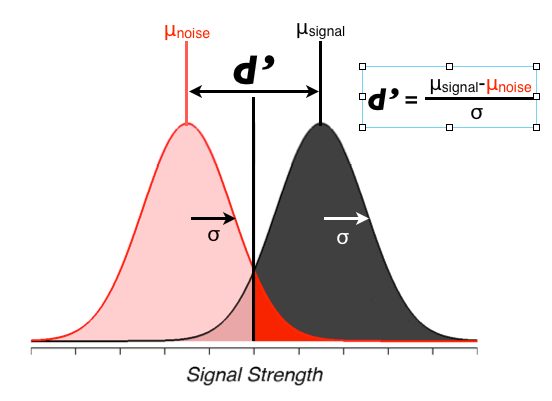

So... How do we calculate dprime with just hits, misses, false alarms, and correct rejections?

d' = z(Hits) - z(False Alarms)

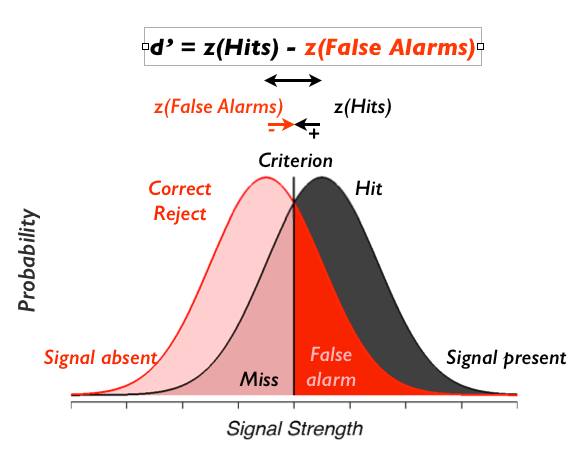

Wait.... what's z? 

z means the distance in units of standard deviation from the center of a gaussian distribution such that the area under the curve to the right of that is the proportion hits or false alarms that we measured in the experiment. By convention, center of the distribution is 0, and  criterion to the left are positive. For example (picture below), if Hits were .84 (or 84%), then z(Hits)=1: 

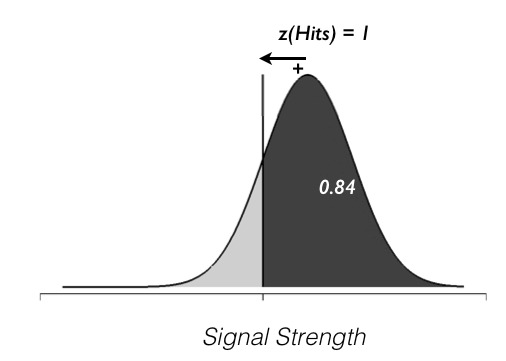

So effectively you're measuring from the center of the signal-present distribution to the criterion (z(Hits)) and the center of the signal-absent distribution to the criterion (-z(FA)) and if you put those two distances together you get the distance between the centers of the two distributions in units that are already normalized by sigma (this should sound a lot like the dprime equation that was in the first dprime picture).

Practical Note for Matlab: To calculate the z score from the area (Hits or False alarms), you can use the icdf function which gives the inverse  of the cumulative density function. It's the cumulative density function since you are interested in the area under the gaussian probability density function, and its the inverse since you are going from the area, back to the z (units of std of the gaussian). 

zHits = icdf('norm',hits,0,1)

zHits = 2.4089

zFalseAlarms = icdf('norm',falseAlarms,0,1)

zFalseAlarms = 1.4325

dPrime = zHits-zFalseAlarms

dPrime = 0.9764

**Does dprime depend on the criterion? ** Put another way, is the d-prime measurement sensitive in any systematic way to changes in the criterion?  You can test this by changing criterion in the previous section and rerunning both that section and this section.

## Generating an ROC curve.

The term ROC curve stands for receiver operating characteristic curve.  We can create an ROC curve by plotting the Hits vs. the False Alarms as a function of the changing criterion. Because an ROC curve is generated by changing the decision criterion, an ROC curve is associated with a single dprime value.  

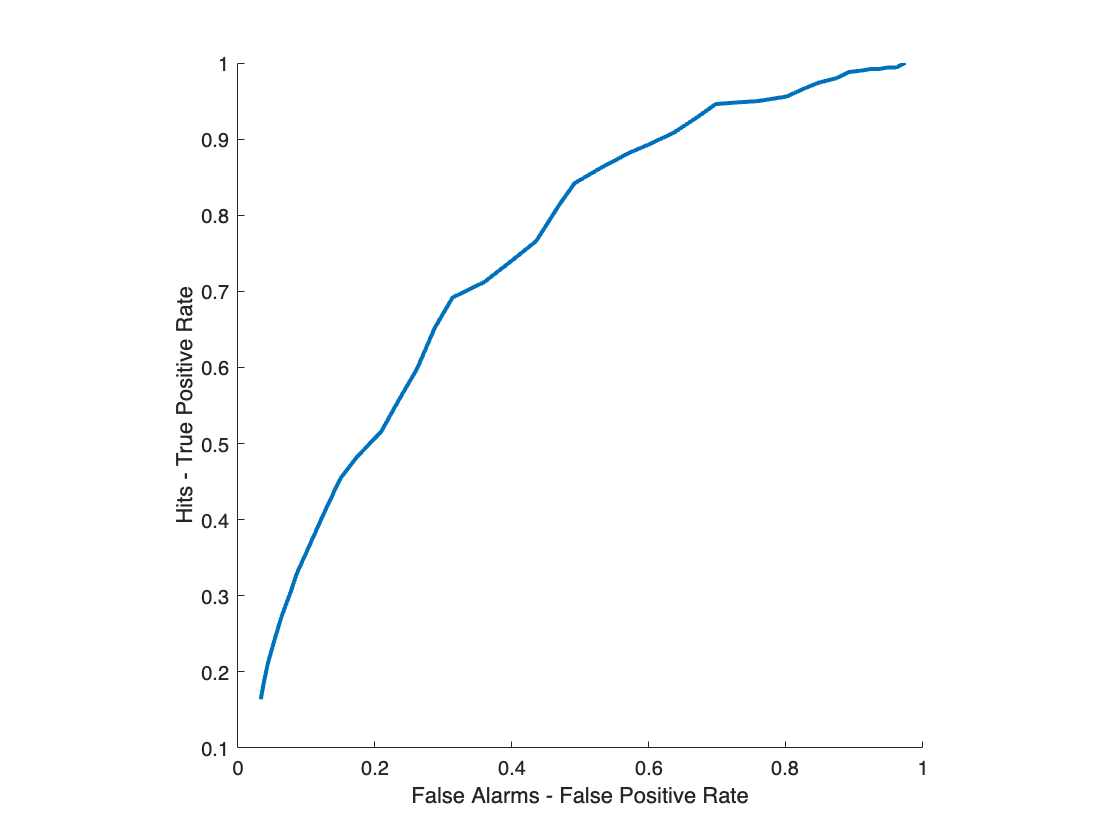


nPresent = sum(signalPresentAbsent==1);
nAbsent = sum(signalPresentAbsent==0);

% loop through different criterion values
changingCriterion = -2:.1:2;
for cc=1:length(changingCriterion)
    % calculate the response for the ideal observer
    cResponse = signal >= changingCriterion(cc);
    
    % compute hits 
    c_hits(cc) = sum(cResponse(signalPresentAbsent==1)==1)/nPresent;

    % compute false alarms
    c_falseAlarms(cc) = sum(cResponse(signalPresentAbsent==0)==1)/nAbsent;
end

figure(); clf;
plot(c_falseAlarms,c_hits,'LineWidth',2); 
xlabel('False Alarms - False Positive Rate');
ylabel('Hits - True Positive Rate')
box off; axis square;